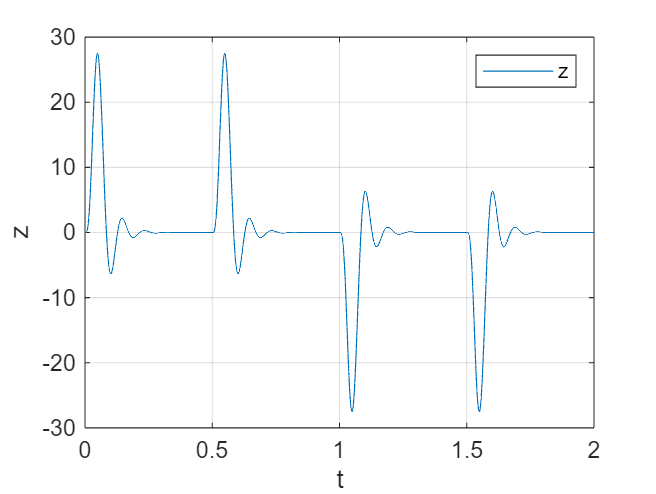

clear;
clc;

load newctftmod.mat
z = [dash,dash,dot,dot];
plot(t,z,'LineStyle','-');
grid on,
xlabel('t'),
ylabel('z'),
legend('z');%4.6a

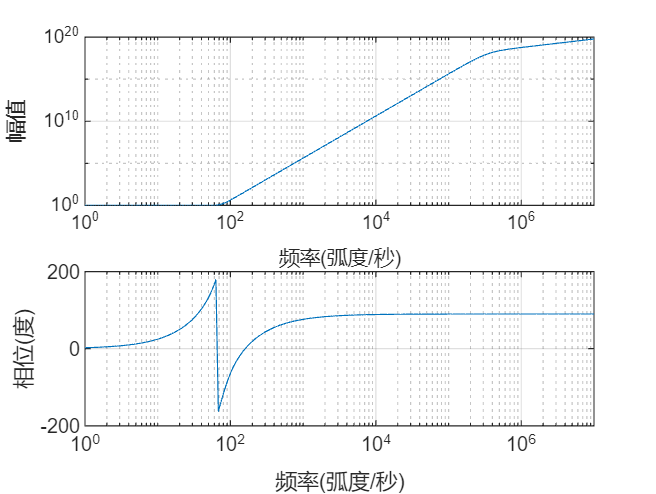


freqs(af,bf)%4.6b

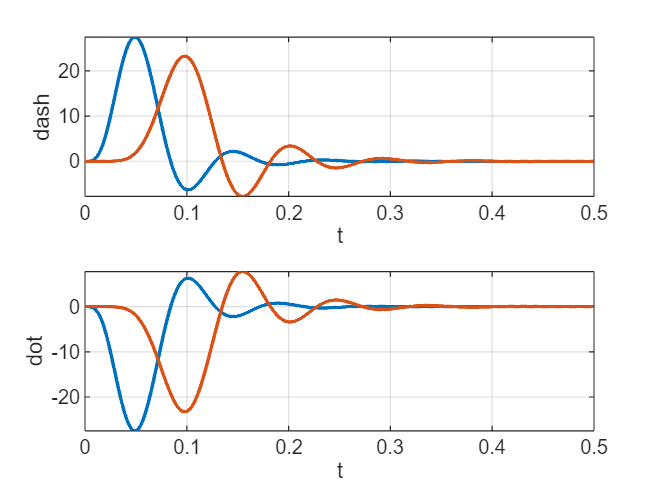


ydash = lsim(bf,af,dash,t(1:length(dash)));
ydot = lsim(bf,af,dot,t(1:length(dot)));
figure
subplot(2,1,1)
plot(t(1:length(dash)),dash,t(1:length(dash)),ydash,'LineWidth',1.5);
xlabel('t'),
ylabel('dash')
grid on;

subplot(2,1,2)
plot(t(1:length(dot)),dot,t(1:length(dot)),ydot,'LineWidth',1.5);
xlabel('t'),
ylabel('dot')
grid on;%4.6c

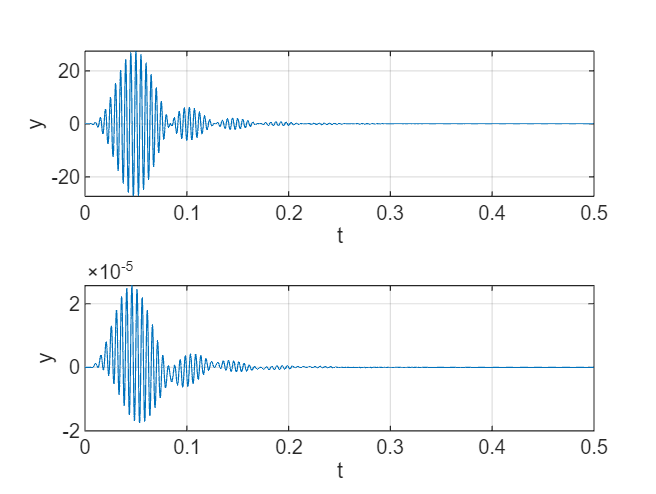


y = dash.*cos(2*pi*f1*t(1:length(dash)));
yo = lsim(bf,af,y,t(1:length(y)));
figure
subplot(2,1,1)
plot(t(1:length(dash)),y);
xlabel('t'),
ylabel('y'),
grid on;
subplot(2,1,2)
plot(t(1:length(dash)),yo);
xlabel('t'),
ylabel('y'),
grid on;%4.2d

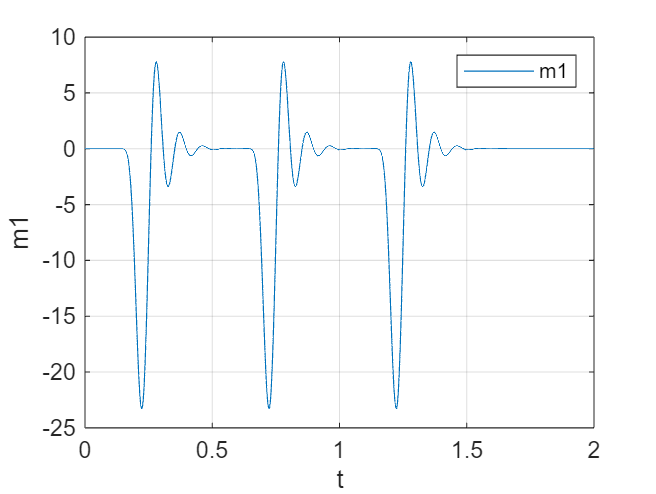


m1t = x.*cos(2*pi*f1*t);
m1 = 2*lsim(bf,af,m1t,t);
figure
plot(t,m1);
xlabel('t'),
ylabel('m1'),
legend('m1'),
grid on;


m2t = x.*cos(2*pi*f*t);
m2 = 2*lsim(bf,af,m2t,t);
figure
plot(t,m2);
xlabel('t'),
ylabel('m2'),
legend('m2'),
grid on;
